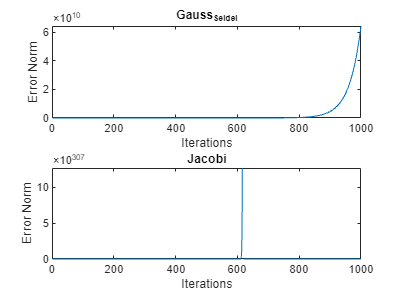

data = load('filtr_dielektryczny.mat');
A = data.A;
b = data.b;
N = 1000:1000:8000;
n = length(N);

[err_norm_direct] = solve_direct(A, b);

[err_norms_Jacobi,err_norm,iterations_Jacobi] = solve_Jacobi(A, b);

[err_norms_Gauss_Seidel,err_norm_Gauss_Seidel,iterations_Gauss_Seidel] = solve_Gauss_Seidel(A, b);
subplot(2,1,1);
plot(err_norms_Gauss_Seidel);
title('Gauss_Seidel')
xlabel('Iterations');
ylabel('Error Norm');
subplot(2,1,2);
plot(err_norms_Jacobi);
xlabel('Iterations');
ylabel('Error Norm');
title('Jacobi');
%print -dpng zadanie6.png

function [err_norm] = solve_direct(A, b)
x = A\b;
err_norm = norm(A*x-b);
end

function [err_norms,err_norm,iterations] = solve_Gauss_Seidel(A, b)
U = triu(A, 1);
L = tril(A, -1);
D = diag(diag(A));
x = ones(length(b),1);
M = -(D+L)\U;
bm = (D+L)\b;
iterations = 0;
err_norm = norm(A*x-b);
err_norms = zeros(1000, 1);
limit = 10^-12;
while err_norm >= limit && iterations < 1000
    x = M*x + bm;
    iterations = iterations + 1;
    err_norms(iterations) = norm(A*x-b);
    err_norm = norm(A*x-b);
end
end

function [err_norms, err_norm,iterations] = solve_Jacobi(A, b)
U = triu(A, 1);
L = tril(A, -1);
D = diag(diag(A));
x = ones(length(b),1);
M = -D\(L+U);
bm = D\b;
iterations = 0;
err_norm = norm(A*x-b);
err_norms = zeros(1000, 1);
limit = 10^-12;
while err_norm >= limit && iterations < 1000
    x = M*x + bm;
    iterations = iterations + 1;
    err_norms(iterations) = norm(A*x-b);
    err_norm = norm(A*x-b);
end
end